## Problem

A particle breaks off from a random point on a rotating flywheel whose radius is r= 1m and the angular velocity is ω= 5. From the point of ejection from the flywheel, track the particle path and determine if the particle will hit the window as shown in the figure below. Perform the simulation 50 times and find the probability of particle hitting the window.

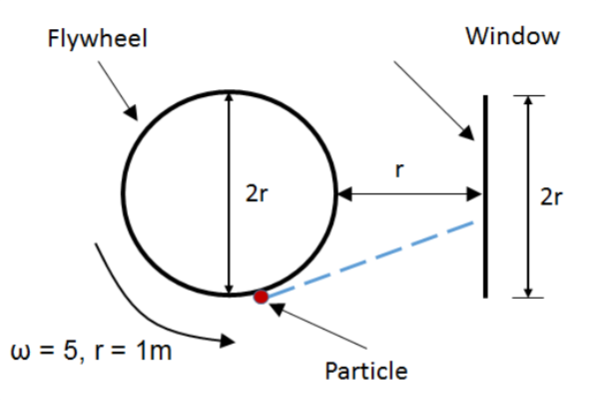

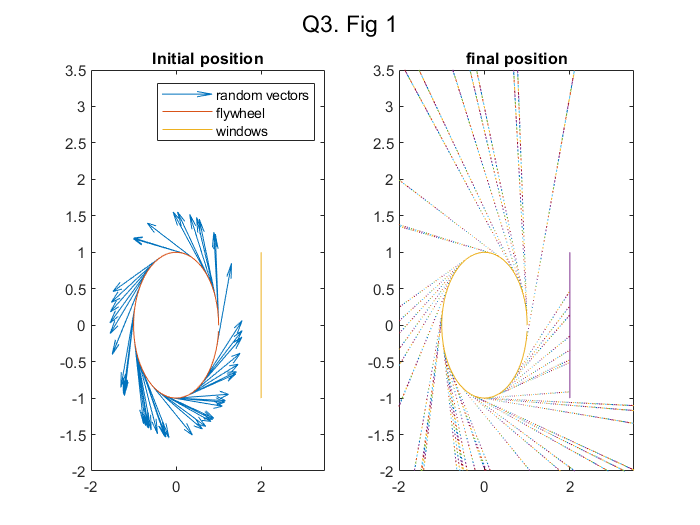

clearvars
n = input('no. of particles = ');
theta = pi - rand([1 n])*2*pi;
%histogram(theta)
r = [cos(theta)' sin(theta)' zeros([1,n])']; % n random position vectors on the flywheel from which particle detaches
w = repmat([0 0 5],([n,1])); % angular velocity vector
v = cross(w,r);

%%plotting for visulization
%compass(r(:,1),r(:,2))
subplot(1,2,1)
quiver(r(:,1),r(:,2),v(:,1),v(:,2),3);
title('Initial position')
hold on
win = [repmat(2,([21,1])) (1:-.1:-1)' zeros(([21,1]))];
plot(cos(0:.1:2*pi),sin(0:.1:2*pi))
plot(win(:,1),win(:,2));
legend('random vectors','flywheel','windows')
xlim([-2 3.5])
ylim([-2 3.5])
hold off

counter = 0;
dt = .01;
for t = 1:1:100
    dis = v*dt;
    r = r + dis;
    collide = 2 - r(:,1) <= .01 & abs(r(:,2)) <= 1;
    if find(collide)
        counter = counter + length(find(collide));
        r(collide,:) = NaN;
    end
    hold on
    subplot(1,2,2)
    title('final position')
    quiver(r(:,1),r(:,2),v(:,1),v(:,2),.03);
    win = [repmat(2,([21,1])) (1:-.1:-1)' zeros(([21,1]))];
    plot(cos(0:.1:2*pi),sin(0:.1:2*pi))
    plot(win(:,1),win(:,2));
    xlim([-2 3.5])
    ylim([-2 3.5])
    hold off
    sgtitle('Q3. Fig 1')
end

disp(['no of collision is ',num2str(counter),' for ',num2str(n),' particles'])

no of collision is 9 for 50 particles


disp(['probability = ',num2str(counter/n)])

probability = 0.18
